## 1: Attach to Arduino 

Before you do anything, press the Reset Button on the Main Arduino and wait for it to display "Waiting for config..."

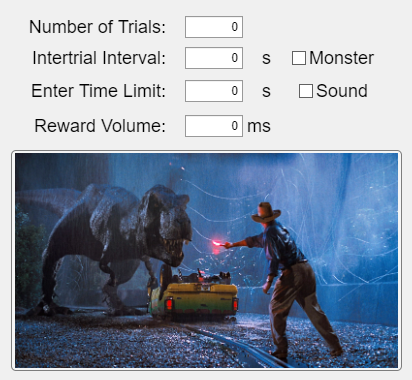

 

clear
clc
app = monsterapp;

arduino_handle = app.arduino_Obj;

## 2: Process Data

****Do not process data until the LCD screen on the Box displays "Complete!" and you have filled out session_filename and save_folder*

- *session_filename example:  "Monster0_01_Training3"*

- *save_folder example: "ex. 9_May_2023"*

session_filename = "Monster1_01_Training5" + ".xls";
save_folder = 'C:\Users\Wallace lab\Desktop\Monster_Task-main\Monster_Task-main\matlab_control\Monster Task Data\' + "12_May_2023";

 

%Wait until all bytes from the serial input buffer are accounted for
while(1)
    check1 = arduino_handle.NumBytesAvailable;
    pause(5);
    check2 = arduino_handle.NumBytesAvailable;
    if(check1==check2)
        break;
    end
end

serial_record = read(arduino_handle,arduino_handle.NumBytesAvailable,"string");
writelines(serial_record, "datalog.txt");

fid = fopen("datalog.txt");
current_line = convertCharsToStrings(fgetl(fid));


Serial Monitor: 

serial_record

serial_record =     "# Trial has ended
     Trial = 1
     trial_duration = 15258
     latency_to_enter = 7138
     latency_to_trigger = 14271
     latency_to_lick = 0
     escape_duration = 0
     mouse_entered = 1
     threat_triggered = 1
     port_licked = 0
     # Trial has ended
     Trial = 2
     trial_duration = 9023
     latency_to_enter = 8035
     latency_to_trigger = 0
     latency_to_lick = 0
     escape_duration = 0
     mouse_entered = 1
     threat_triggered = 0
     port_licked = 0
     # Trial has ended
     Trial = 3
     trial_duration = 4767
     latency_to_enter = 3781
     latency_to_trigger = 0
     latency_to_lick = 0
     escape_duration = 0
     mouse_entered = 1
     threat_triggered = 0
     port_licked = 0
     # Trial has ended
     Trial = 4
     trial_duration = 37092
     latency_to_enter = 16053
     latency_to_trigger = 36105
     latency_to_lick = 0
     escape_duration = 0
     mouse_entered = 1
     threat_triggered = 1
     port_licked = 0
     


% Initialize current_trial
current_trial = 0;

% Initialize trial variables
trial_duration_var = zeros(10,2);
latency_to_enter_var = zeros(10,2);
latency_to_trigger_var = zeros(10,2);
latency_to_lick_var = zeros(10,2);
escape_duration_var = zeros(10,2);
mouse_entered_var = zeros(10,2);
threat_triggered_var = zeros(10,2);
port_licked_var = zeros(10,2);

% Fill trial variables
while isstring(current_line)
    
    % increase current_trial
    if contains(current_line, "# Trial has ended")
        current_trial = current_trial + 1;
    end 
    
    % Fill trial_duration_var
    if contains(current_line, 'trial_duration = ')
        trial_duration_var(current_trial, :) = [
            current_trial, ...
            str2double(erase(current_line,'trial_duration = '))
             ];
    end

    % Fill latency_to_enter_var
    if contains(current_line, 'latency_to_enter = ')
        latency_to_enter_var(current_trial, :) = [
            current_trial, ...
            str2double(erase(current_line, 'latency_to_enter = '))
            ];
    end

    % Fill latency_to_trigger_var
    if contains(current_line, 'latency_to_trigger = ')
        latency_to_trigger_var(current_trial, :) = [
            current_trial, ...
            str2double(erase(current_line, 'latency_to_trigger = '))
            ];
    end    

    % Fill latency_to_lick_var
    if contains(current_line, 'latency_to_lick = ')
        latency_to_lick_var(current_trial, :) = [
            current_trial, ...
            str2double(erase(current_line, 'latency_to_lick = '))
            ];
    end    

    % Fill escape_duration_var
    if contains(current_line, 'escape_duration = ')
        escape_duration_var(current_trial, :) = [
            current_trial, ...
            str2double(erase(current_line, 'escape_duration = '))
            ];
    end

    % Fill mouse_entered_var
    if contains(current_line, 'mouse_entered = ')
        mouse_entered_var(current_trial, :) = [
            current_trial, ...
            str2double(erase(current_line, 'mouse_entered = '))
            ];
    end

    % Fill threat_triggered_var
    if contains(current_line, 'threat_triggered = ')
        threat_triggered_var(current_trial, :) = [
            current_trial, ...
            str2double(erase(current_line, 'threat_triggered = '))
            ];
    end

    % Fill port_licked_var
    if contains(current_line, 'port_licked = ')
        port_licked_var(current_trial, :) = [
            current_trial, ...
            str2double(erase(current_line, 'port_licked = '))
            ];
    end    

    %move to next line after checking through all the if statements
    current_line = convertCharsToStrings(fgetl(fid));

end

trial_duration = trial_duration_var(:,2);
latency_to_enter = latency_to_enter_var(:,2);
latency_to_trigger = latency_to_trigger_var(:,2);
latency_to_lick = latency_to_lick_var(:,2);
escape_duration = escape_duration_var(:,2);
mouse_entered = mouse_entered_var(:,2);
threat_triggered = threat_triggered_var(:,2);
port_licked = port_licked_var(:,2);


Formatted Session Data:


session_data = table( ...
    trial_duration, ... 
    latency_to_enter, ...
    latency_to_trigger, ...
    latency_to_lick, ...
    escape_duration, ...
    mouse_entered, ...
    threat_triggered, ...
    port_licked ...
    )

session_data = 10×8 table
    trial_duration    latency_to_enter    latency_to_trigger    latency_to_lick    escape_duration    mouse_entered    threat_triggered    port_licked
    ______________    ________________    __________________    _______________    _______________    _____________    ________________    ___________

           15258            7138                14271                    0                  0               1                 1                 0     
            9023            8035                    0                    0                  0               1                 0                 0     
            4767            3781                    0                    0                  0    


cd(save_folder)
writetable(session_data, session_filename);

disp("Saved!")

Saved!



cd 'C:\Users\Wallace lab\Desktop\Monster_Task-main\Monster_Task-main\matlab_control'